## Basics

Rechargeable Li-ion batteries have been transforming our lives since the last two decades, the current focus on electrification of mobility sector and also the need for large energy storage devices to help with the intermittent renewables, there is a lot to be understood about our batteries and the materials that go into them to make higher energy density and also safer to use batteries that are manufactured in a sustainable way. 

**Battmo** is a powerful tool for conducting battery simulations, aiding in the understanding of battery performance, lifecycle, and safety concerns. It utilizes continuum scale P2D (pseudo-two-dimensional) simulations based on the Doyle-Fuller-Newman (DFN) model, see part 2 of the modelling guide for more information. By inputting material parameters for the various components of the battery, Battmo can simulate capacity losses that occur during charge-discharge cycles. This allows users to investigate how different parameters impact cycle life and stability in a real battery system.

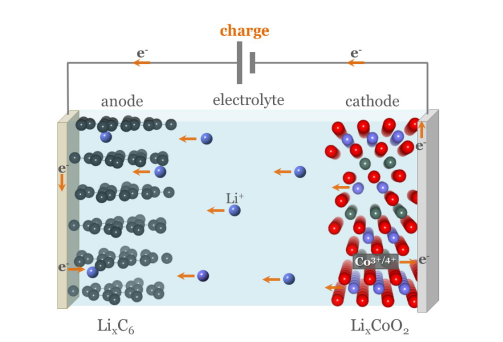

Let's begin by explaining the fundamental principles and operation of a lithium-ion (Li-ion) battery. The battery cell consists of three main components: the anode, typically made of a graphitic material; the cathode, usually composed of a transition metal oxide; and an electrolyte, which is an organic solvent containing a lithium salt. We will look at the exact types of materials used for these components in detail later. A rechargeable Li-ion battery operates on the principles of intercalation and deintercalation of lithium ions. During charging and discharging cycles, lithium ions move between the anode and cathode through the electrolyte. Concurrently, electrons are driven through the external circuit, providing electrical energy to connected devices. The process is depicted in the accompanying figure.

During a typical discharge cycle, 

The reaction taking place at the cathode (postive electrode):


$$\[
\text{[NiMnCo]O}_2 + \text{Li}^{+} + e^{-} \rightarrow \text{Li[NiMnCo]O}_2
\]$$


At the anode (negative electrode):


$$% Anode Reaction (Discharge)
\[
\text{LiC}_6 \rightarrow \text{C}_6 + \text{Li}^{+} + e^{-}
\]
$$


The overall cell reaction:


$$% Overall Cell Reaction (Discharge)
\[
\text{LiC}_6 + \text{[NiMnCo]O}_2 \rightarrow \text{C}_6 + \text{Li[NiMnCo]O}_2
\]
$$


**Electrodes:**

Porous particles

**Cathode**:

**Anode:**

**Electrolyte:**

 **BattMo** uses JSON to manage input parameters. This allows you to easily save, document, and share complete parameter sets from specific simulations. If you are new to JSON, you can learn more about it [here](https://www.w3schools.com/js/js_json_intro.asp). 

For the rest of this guide, we will use a starter JSON file, [sample_input.json](https://github.com/BattMoTeam/BattMo/blob/main/Examples/JsonDataFiles/sample_input.json) that describes a Lithium nickel manganese cobalt oxide(NMC) - Graphite cell [1] with LiPF6 [2] as the electrolyte, in a 1D cell according to [BattMo's JSON input specification](https://battmoteam.github.io/BattMo/json.html#json-input-specification). 

This sample_input.json file contains all the information needed to run the simulation. These parameters are neatly arranged into structured schemas. Unless otherwise specified, BattMo uses [SI base units](https://www.nist.gov/si-redefinition/definitions-si-base-units) for physical quantities.

- A schema for the [**geometry**](https://battmoteam.github.io/BattMo/geometryinput.html#batterygeneratorp2d)**, **contains the dimensions of the different components within the battery

- A schema for the [**battery cell material parameters**](https://battmoteam.github.io/BattMo/json.html#material-parameters)**, **contains material parameters for the NMC - Graphite cell sourced from the literature.

- A schema for the **initialization of the state of the battery,** specifies the initial state of the battery, including the initial state of charge (SOC).

- A schema for [control model](https://battmoteam.github.io/BattMo/controlinput.html#control-models), defines the charging an discharging protocols,

- A schema for the [**time stepping**](https://battmoteam.github.io/BattMo/json.html#time-stepping-parameters)**,**

- A schema for the [**solver parameters**](https://battmoteam.github.io/BattMo/json.html#time-stepping-parameters)**, **specifies the parameters for the numerical solver used in the simulation.

- A schema for the [**output specification**](https://battmoteam.github.io/BattMo/json.html#output-parameters)

As a first step, let us look at how a battery looks in BattMo. We offer convenient built-in functions that  help in parsing and visualizing data.

**Parse and Visualize your battery grid:**

- Load the default sample_input.json file using parseBattmoJson function.

- Visualize the 1D system using plotBatteryGrid.

- Merge the default file with a 3D Geometry File with mergeJsonStructs and visualise the 3D system

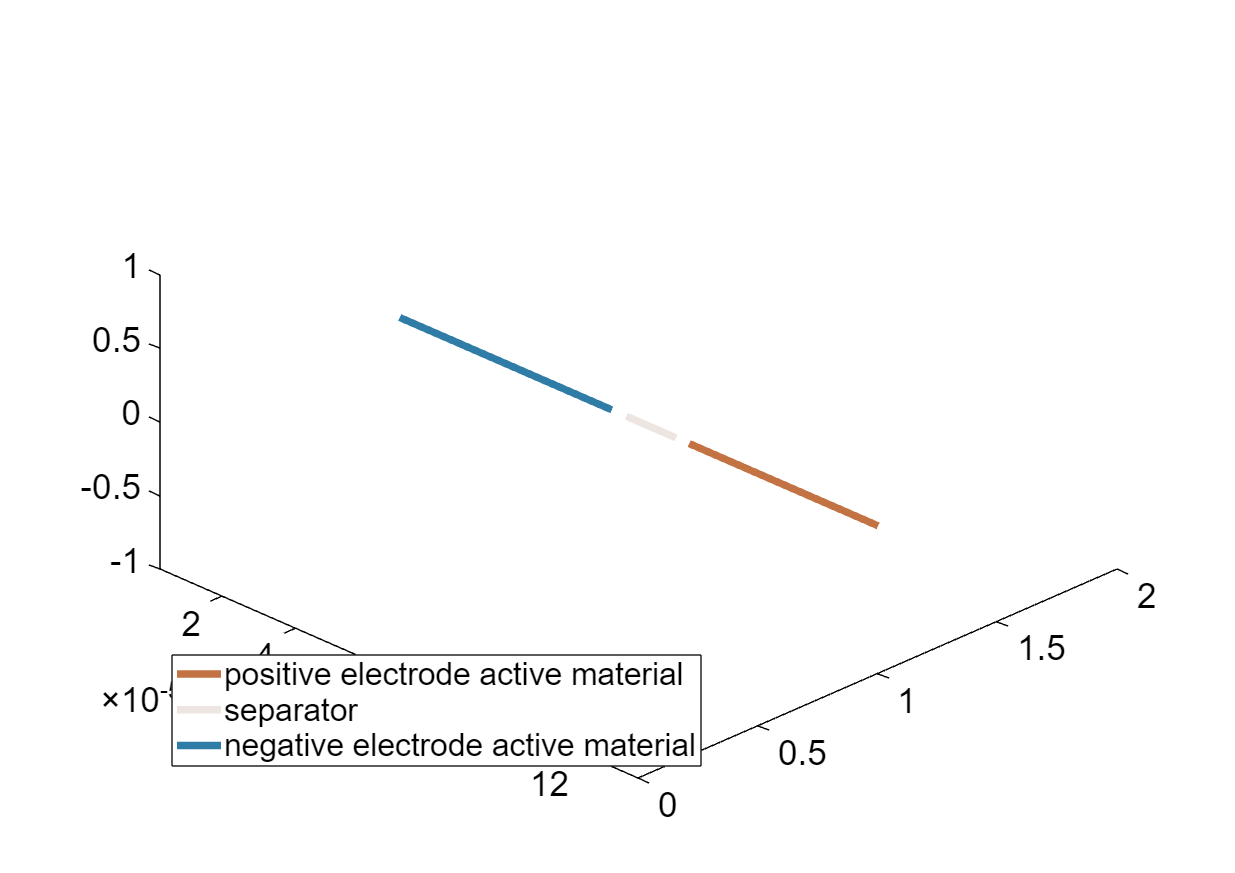

jsonstruct_default = parseBattmoJson('Examples/JsonDataFiles/sample_input.json');
model_1d = setupModelFromJson(jsonstruct_default);
% use the plotBatteryGrid function to show the grid
plotBatteryGrid(model_1d)
axis tight
view(45,45)

jsonstruct_3d_geometry = parseBattmoJson('Examples/JsonDataFiles/geometry3d.json');
jsonstruct_modified_3d = mergeJsonStructs({jsonstruct_3d_geometry , ...
    jsonstruct_default});

parameter include_current_collectors is assigned twice with different values. we use the value from first jsonstruct.
parameter Geometry.case is assigned twice with different values. we use the value from first jsonstruct.
parameter NegativeElectrode.Coating.thickness is assigned twice with different values. we use the value from first jsonstruct.
parameter NegativeElectrode.Coating.N is assigned twice with different values. we use the value from first jsonstruct.
parameter NegativeElectrode.CurrentCollector.N is assigned twice with different values. we use the value from first jsonstruct.
parameter PositiveElectrode.Coating.thickness is assigned twice with different values. we use the value from first jsonstruct.
parameter PositiveElectrode.Coating.N is assigned twice with different values. we use the value from first jsonstruct.
parameter PositiveElectrode.CurrentCollector.N is assigned twice with different values. we use the value from first jsonstruct.
parameter Separator.thickness

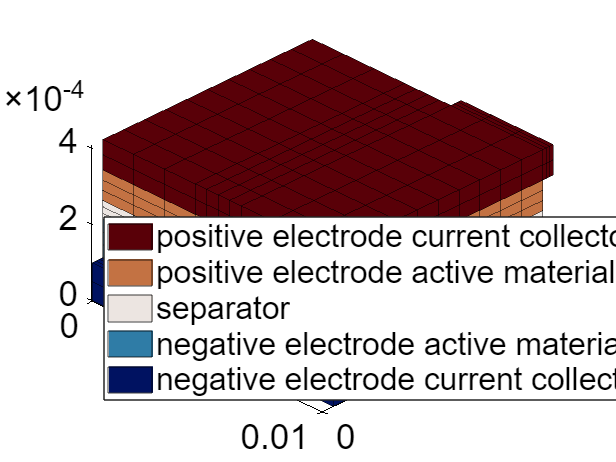

model_3d = setupModelFromJson(jsonstruct_modified_3d);
plotBatteryGrid(model_3d)
% make the axis tight and set the camera viewing angle
axis tight
view(45,45)

## Characterising a battery

A good battery should posess high energy density, ensuring it can store a significant amount of energy relative to its size and weight. Additionally, it should maintain a long cycle life, allowing it to endure numerous charge and discharge cycles without significant degradation. Minimal energy loss during these cycles is crucial, ensuring efficient energy usage and prolonged operational efficiency. 

Let's delve into essential terms and parameters crucial for understanding batteries and their simulation in Battmo. These terms and parameters help in evaluating and comparing battery performance and characteristics.

**Definitions:**

- Lower (upper) cut off voltage:The minimum (maximum) allowable voltage. It is this voltage that generally defines the “empty” ("full") state of the battery, this is set as an input parameter in the simulation.The value depends on the materials used in the cell

- [C-rate](https://w3id.org/emmo/domain/electrochemistry#electrochemistry_e1fd84eb_acdb_4b2c_b90c_e899d552a3ee) (cycling rate): this is the rate at which a battery is discharged in relation to its maximum capacity. Specifically, a 1C rate signifies that the discharge current will exhaust the total battery capacity in 1 hour. The CRate chosen depends on your application,this is set as an input parameter in the simulation

- State of Charge(SOC %): ratio of the current battery capacity to its maximum capacity, this is set as an input parameter in the simulation

- [OpenCircuitVoltage](https://w3id.org/emmo/domain/electrochemistry#electrochemistry_9c657fdc_b9d3_4964_907c_f9a6e8c5f52b) (OCV): The voltage between the cathode and the anode with no external load, to calculate this in Battmo,one can use a very small charge/discharge current, a CRate of C/20. OCV curves are typically plotted as voltage versus state of charge (SOC), the curves depend on the chemistry of the cell.

**Characterization of a cell:**

- [Capacity](https://w3id.org/emmo/domain/electrochemistry#electrochemistry_791c1915_a791_4450_acd8_7f94764743b5) (Ah): electric charge which a cell or battery can deliver under specified discharge conditions, calculated as a product of discharge current and discharge time. Increasing the CRate decreases the capacity due to increasing internal losses.

- Nominal Capacity (Ah): the rated capacity that is representative of the typical value associated with a cell as stated by the manufacturer

- Theoretical capacity: maximum possible charge, a cell can store, it is a fixed value determined by the amount and type of active material used in the electrodes.

- Energy(Wh):calculated as the product of capacity and the average discharge voltage when discharged at a specific C-rate,Increasing the CRate decreases the energy.

- [Energy density](https://w3id.org/emmo/domain/electrochemistry#electrochemistry_4aa1b96e_44a0_4b1a_a0ac_723d0223d80b) (Wh/l): calculated as the energy divided by the volume of the cell

- Specific energy (Wh/kg): calculated as the energy divided by the mass of the cell

- Efficiency: ratio of the energy released during discharge to the energy stored during charge. This parameter indicates how effectively a battery converts stored energy into usable energy.

**Charging/Discharging protocols:**

A Li-ion battery is typically charged using a constant current/constant voltage protocol (CCCV). This means the battery is initially charged at a constant current until it reaches a maximum voltage (upperCutoffVoltage). Once this voltage is reached, the protocol switches to maintaining a constant voltage between the terminal while the charging current gradually decreases. This is set using the [control model schema](https://battmoteam.github.io/BattMo/controlinput.html#control-models). During discharge, a constant current (CC) is drawn from the cell until the voltage reaches the minimum cut-off voltage (lowerCutoffVoltage) in  of the cell.

**CC discharge voltage profile of NMC-Graphite cell:**

Now we are ready to run our first simulation. Refer to the `sample_input.json` for the exact values. In summary, we will simulate the constant current (CC) discharge of an NMC-Graphite system, starting from a 100% state of charge (SOC) at a C-rate of 1. Before running the actual simulation, the function `computeCellCapacity.m` processes the material parameters for the active materials in the electrodes, along with their mass fractions, to compute the maximum cell capacity (theoretical capacity). Since capacity is given by the formula $\(\text{capacity} = \frac{1}{\text{C-rate}} \times \text{discharge current}\)$, the discharge current can be calculated accordingly. *Can we show the theorectical capacity  value, 'cell specification summary'?*  For this system, the typical lower and upper cutoff voltages are 2.4V and 4.1V, respectively. The simulation stops when the lower cut-off voltage is reached.

jsonstruct = parseBattmoJson('Examples/JsonDataFiles/sample_input.json');% parse the sample_input.json
disp(jsonstruct.Control);% see the default values set in the control policy

         controlPolicy: 'CCDischarge'
                 CRate: 1
    lowerCutoffVoltage: 2.4000
    upperCutoffVoltage: 4.1000
             dIdtLimit: 0.0100
             dEdtLimit: 0.0100
            rampupTime: 0.1000



The simulation can then be executed using the `runBatteryJson` function. 

jsonstruct.TimeStepping.totalTime = (1./jsonstruct.Control.CRate) .* 3600 .* 1.2;
output = runBatteryJson(jsonstruct); 

Solving timestep 01/45:                     -> 3 Seconds, 375 Milliseconds
Solving timestep 02/45: 3 Seconds, 375 Milliseconds -> 6 Seconds, 750 Milliseconds
Solving timestep 03/45: 6 Seconds, 750 Milliseconds -> 13 Seconds, 500 Milliseconds
Solving timestep 04/45: 13 Seconds, 500 Milliseconds -> 27 Seconds
Solving timestep 05/45: 27 Seconds          -> 54 Seconds
Solving timestep 06/45: 54 Seconds          -> 108 Seconds
Solving timestep 07/45: 108 Seconds         -> 216 Seconds
Solving timestep 08/45: 216 Seconds         -> 324 Seconds
Solving timestep 09/45: 324 Seconds         -> 432 Seconds
Solving timestep 10/45: 432 Seconds         -> 540 Seconds
Solving timestep 11/45: 540 Seconds         -> 648 Seconds
Solving timestep 12/45: 648 Seconds         -> 756 Seconds
Solving timestep 13/45: 756 Seconds         -> 864 Seconds
Solving timestep 14/45: 864 Seconds         -> 972 Seconds
Solving timestep 15/45: 972 Seconds         -> 1080 Seconds
Solving timestep 16/45: 1080 Seconds      

The output structure returns among other thing the model and the states. The model contains information about the setup of the model and initial conditions, while states contains the results of the simulation at each timestep. The model can also output the energy, energy density and specific energy of the system.

disp(output);

             model: [1×1 Battery]
       inputparams: [1×1 BatteryInputParams]
          schedule: [1×1 struct]
         initstate: [1×1 struct]
              time: [42×1 double]
                 E: [42×1 double]
                 I: [42×1 double]
            states: {42×1 cell}
            energy: [41×1 double]
     energyDensity: [41×1 double]
    specificEnergy: []



We can then plot the voltage vs capacity from the output to obtain the cell discharge profile. The voltage curve typically exhibits three distinct parts:

- An initial drop, caused by internal resistances and the activation of electrochemical processes.

- A plateau region where the voltage remains relatively flat. A longer plateau region in a battery's discharge profile is beneficial as it signifies that the voltage remains stable with minimal fluctuations across a substantial portion of its capacity, ensuring consistent and efficient energy delivery. The length and voltage of this plateau depend on the cell chemistry.

- A final drop as the cell approaches its capacity limit.

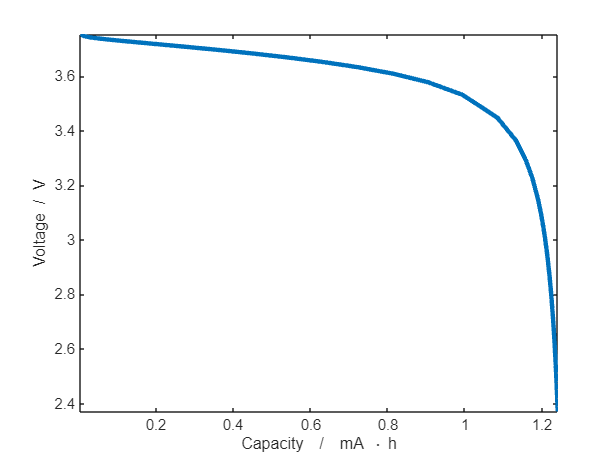

function plotDischargeCurve(output)

    % Extract the states from the output
    states = output.states;

    % Extract the time, voltage, and current quantities
    time = cellfun(@(state) state.time, states);
    voltage = cellfun(@(state) state.('Control').E, states);
    current = cellfun(@(state) state.('Control').I, states);

    % Calculate the capacity
    capacity = time .* current;

    % Instantiate an empty figure
    figure()

    % Plot the discharge curve in the figure
    plot((capacity / (hour * milli)), voltage, '-', 'linewidth', 3)

    % Label the axes
    xlabel('Capacity  /  mA \cdot h')

parameter Control.controlPolicy is assigned twice with different values. we use the value from first jsonstruct.
parameter Control.lowerCutoffVoltage is assigned twice with different values. we use the value from first jsonstruct.


    ylabel('Voltage  /  V')

    % Adjust the axis limits
    axis tight
end
plotDischargeCurve(output)

*Should we add the influence of C-rates here, copy from notebook example?*

## **Influence of structural and material parameters on the capacity**

For a given cell chemistry, the capacity of a cell is constrained by the number of lithium ions that can be safely intercalated and deintercalated from the electrodes. As cells age, they experience irreversible loss of lithium ions, which reduces their capacity over time. We will look at ageing mechanisms in a later chapter. Now, let's examine how material parameters affect cell capacity. One method to increase a cell's capacity, or the amount of energy stored, is by increasing the mass loading, which is the amount of active material per unit area of the electrode. This can be achieved by reducing the number of pores to increase the effective density or by increasing the mass fraction of the coating relative to other components, such as binders and additives. Alternatively, the thickness of the electrode can be increased while maintaining the same ratio of components, thereby adding more active material.

**(i) Increasing the thickness of the anode / cathode:**

**Anode:**

Please set the electrode type to be "anode" in the code below. We maintain the NMC cathode at a constant thickness while increasing the graphite electrode thickness from 32 micrometers to 72 micrometers to observe its impact on the capacity of our 1D system. Additionally, we switch to the CC-CV protocol, where we first charge the cell with constant current-constant voltage (CC-CV) and then discharge it at constant current. 

We plot the discharge curve and observe that the capacity increases for 32 < 45 < 64 micrometers. However, beyond 64 micrometers, further increasing the thickness has no effect on capacity. This is because the amount of lithium in this scenario is limited by the NMC cathode. Although more lithium can initially intercalate into the thicker graphite, beyond a certain thickness, there is no additional lithium available to intercalate into the graphite that can be extracted during discharge. Therefore, the capacity remains unchanged.

**Cathode:**

Please set the electrode type to be "cathode" in the code below. We increase the thickness of the NMC cathode from 32 micrometers to 72 micrometers. In this scenario, the negative electrode is intentionally oversized relative to the capacity of the positive electrode by approximately 1.3 times. This design ensures that the capacity of the negative electrode exceeds that of the positive electrode, thereby helping to prevent dangerous lithium plating. 

We've increased the thickness of the NMC cathode from 32 micrometers to 72 micrometers. In this setup, the negative electrode intentionally exceeds the capacity of the positive electrode by approximately 1.3 times. This approach helps prevent dangerous lithium plating by ensuring the negative electrode's capacity is higher.

The thicker electrode indeed shows a notable increase in capacity. However, this comes with its own set of challenges. The longer diffusion pathways for lithium ions within the electrode, higher overpotentials, and extended paths for electronic transport all contribute to a reduced rate capacity. Despite the increase in energy density, these factors cause the capacity to diminish more rapidly at higher discharge rates, this makes it unsuitable for high power applications.* I cant see the effect here should I change some other parameter to see it in this toy example?*

% create a vector of diffent thickness values
thickness = [32,45,64,72,].*micro;
markers={'-',"-",'o',"x"};
jsonstruct_default = parseBattmoJson('Examples/JsonDataFiles/sample_input.json');
cccv_control_protocol = parseBattmoJson('cccv_control_charge.json');%loads the CCCV protocol
jsonstruct_modified = mergeJsonStructs({cccv_control_protocol, jsonstruct_default});
% instantiate and empty cell array to store the outputs of the simulations
output = cell(size(thickness));

% instantiate an empty figure
figure()

% Specify the type of electrode to modify
%electrodeType = 'NegativeElectrode'; % or 'PositiveElectrode'
electrodeType = 'PositiveElectrode'; % or 'PositiveElectrode'
dischargeRate ='high'; % or 'default'

% use a for-loop to iterate through the vector of c-rates
for i = 1 : numel(thickness)
    % Modify the value for the coating thickness for the specified electrode type
    if strcmp(electrodeType, 'NegativeElectrode')
        jsonstruct_modified.NegativeElectrode.Coating.thickness = thickness(i);
    elseif strcmp(electrodeType, 'PositiveElectrode')
        if strcmp(dischargeRate, 'high')
            jsonstruct_modified.CRate=10;
        end
        jsonstruct_modified.PositiveElectrode.Coating.thickness = thickness(i);
        jsonstruct_modified.NegativeElectrode.Coating.thickness = thickness(i)*1.3;
    else
        error('Unknown electrode type specified');
    end
    
    % run the simulation and store the results in the output cell array
    output{i} = runBatteryJson(jsonstruct_modified);
    
    % retrieve the states from the simulation result
    states = output{i}.states;

Solving timestep 01/45:                      -> 6 Seconds, 187 Milliseconds
Solving timestep 02/45: 6 Seconds, 187 Milliseconds -> 12 Seconds, 375 Milliseconds
Solving timestep 03/45: 12 Seconds, 375 Milliseconds -> 24 Seconds, 750 Milliseconds
Solving timestep 04/45: 24 Seconds, 750 Milliseconds -> 49 Seconds, 500 Milliseconds
Solving timestep 05/45: 49 Seconds, 500 Milliseconds -> 99 Seconds
Solving timestep 06/45: 99 Seconds           -> 198 Seconds
Solving timestep 07/45: 198 Seconds          -> 396 Seconds
Solving timestep 08/45: 396 Seconds          -> 594 Seconds
Solving timestep 09/45: 594 Seconds          -> 792 Seconds
Solving timestep 10/45: 792 Seconds          -> 990 Seconds
Solving timestep 11/45: 990 Seconds          -> 1188 Seconds
Solving timestep 12/45: 1188 Seconds         -> 1386 Seconds
Solving timestep 13/45: 1386 Seconds         -> 1584 Seconds
Solving timestep 14/45: 1584 Seconds         -> 1782 Seconds
Solving timestep 15/45: 1782 Seconds         -> 1980 Second

Solving timestep 01/45:                      -> 6 Seconds, 187 Milliseconds
Solving timestep 02/45: 6 Seconds, 187 Milliseconds -> 12 Seconds, 375 Milliseconds
Solving timestep 03/45: 12 Seconds, 375 Milliseconds -> 24 Seconds, 750 Milliseconds
Solving timestep 04/45: 24 Seconds, 750 Milliseconds -> 49 Seconds, 500 Milliseconds
Solving timestep 05/45: 49 Seconds, 500 Milliseconds -> 99 Seconds
Solving timestep 06/45: 99 Seconds           -> 198 Seconds
Solving timestep 07/45: 198 Seconds          -> 396 Seconds
Solving timestep 08/45: 396 Seconds          -> 594 Seconds
Solving timestep 09/45: 594 Seconds          -> 792 Seconds
Solving timestep 10/45: 792 Seconds          -> 990 Seconds
Solving timestep 11/45: 990 Seconds          -> 1188 Seconds
Solving timestep 12/45: 1188 Seconds         -> 1386 Seconds
Solving timestep 13/45: 1386 Seconds         -> 1584 Seconds
Solving timestep 14/45: 1584 Seconds         -> 1782 Seconds
Switch control type from CV_charge2 to CC_discharge1
Solvin

Solving timestep 01/45:                      -> 6 Seconds, 187 Milliseconds
Solving timestep 02/45: 6 Seconds, 187 Milliseconds -> 12 Seconds, 375 Milliseconds
Solving timestep 03/45: 12 Seconds, 375 Milliseconds -> 24 Seconds, 750 Milliseconds
Solving timestep 04/45: 24 Seconds, 750 Milliseconds -> 49 Seconds, 500 Milliseconds
Solving timestep 05/45: 49 Seconds, 500 Milliseconds -> 99 Seconds
Solving timestep 06/45: 99 Seconds           -> 198 Seconds
Solving timestep 07/45: 198 Seconds          -> 396 Seconds
Solving timestep 08/45: 396 Seconds          -> 594 Seconds
Solving timestep 09/45: 594 Seconds          -> 792 Seconds
Solving timestep 10/45: 792 Seconds          -> 990 Seconds
Solving timestep 11/45: 990 Seconds          -> 1188 Seconds
Solving timestep 12/45: 1188 Seconds         -> 1386 Seconds
Solving timestep 13/45: 1386 Seconds         -> 1584 Seconds
Solving timestep 14/45: 1584 Seconds         -> 1782 Seconds
Switch control type from CV_charge2 to CC_discharge1
Solvin

Solving timestep 01/45:                      -> 6 Seconds, 187 Milliseconds
Solving timestep 02/45: 6 Seconds, 187 Milliseconds -> 12 Seconds, 375 Milliseconds
Solving timestep 03/45: 12 Seconds, 375 Milliseconds -> 24 Seconds, 750 Milliseconds
Solving timestep 04/45: 24 Seconds, 750 Milliseconds -> 49 Seconds, 500 Milliseconds
Solving timestep 05/45: 49 Seconds, 500 Milliseconds -> 99 Seconds
Solving timestep 06/45: 99 Seconds           -> 198 Seconds
Solving timestep 07/45: 198 Seconds          -> 396 Seconds
Solving timestep 08/45: 396 Seconds          -> 594 Seconds
Solving timestep 09/45: 594 Seconds          -> 792 Seconds
Solving timestep 10/45: 792 Seconds          -> 990 Seconds
Solving timestep 11/45: 990 Seconds          -> 1188 Seconds
Solving timestep 12/45: 1188 Seconds         -> 1386 Seconds
Solving timestep 13/45: 1386 Seconds         -> 1584 Seconds
Switch control type from CV_charge2 to CC_discharge1
Solving timestep 14/45: 1584 Seconds         -> 1782 Seconds
Solvin

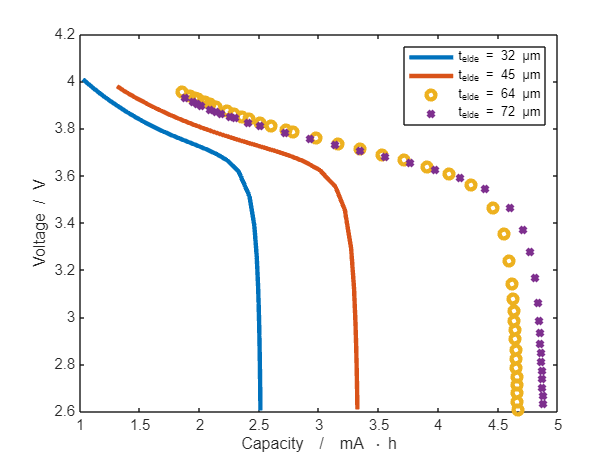

    
    % extract the time and voltage quantities
    time = cellfun(@(state) state.time, states);
    voltage = cellfun(@(state) state.('Control').E, states);

    current = cellfun(@(state) state.('Control').I, states);
    % calculate the capacity
    capacity = time .* current;
    % plot only the discharge part of the curve in the figure to observe the capacity
    start_index = find(capacity > 0, 1, 'first');
    end_index = find(capacity > 0, 1, 'last');
    plot((capacity(start_index:end_index)/(hour*milli)), voltage(start_index:end_index), markers{i}, 'linewidth', 3);
    hold on
end
hold off
xlabel('Capacity  /  mA \cdot h')
ylabel('Voltage  /  V')
legend( 't_{elde} = 32 µm', 't_{elde} = 45 µm','t_{elde} = 64 µm','t_{elde} = 72 µm')

**(ii) Increasing the effective density**